In this document we will explore the concept of a "valid design" for a single variable-curvature segment. We will first implement the forward kinematics of a rod with linear curvature. Then, we will compute the externally induced forces and moments along it at each point, and plot these points in the reaction space. Finally, we will compute the internal reaction forces along an arm held at that shape, and also plot these points within the reaction space.

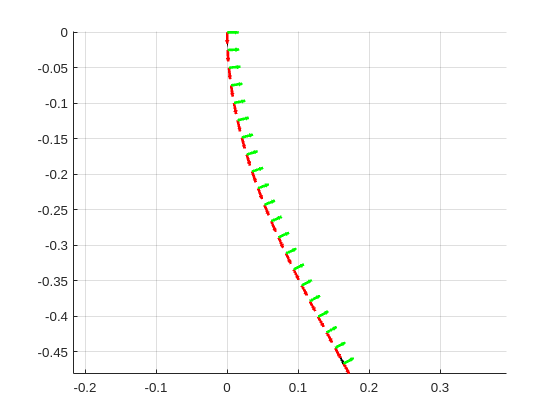

% Define arm base curve
a = -1;
b = 1;

l = 0.5;
f_affine_curvature = @(s) [
    l*ones(size(s));
    zeros(size(s));
    a*s + b
];

g_0 = Pose2.hat([0, 0, -pi/2]);
N_poses = 20;
s = linspace(0, 1, N_poses);
poses = f_calc_poses(g_0, f_affine_curvature, N_poses);
segment_twists = f_affine_curvature(s);

ax = axes(figure());
plot_poses(poses, ax);
grid on

Now let's apply a load to the tip of this rod and consider the reactions across it:

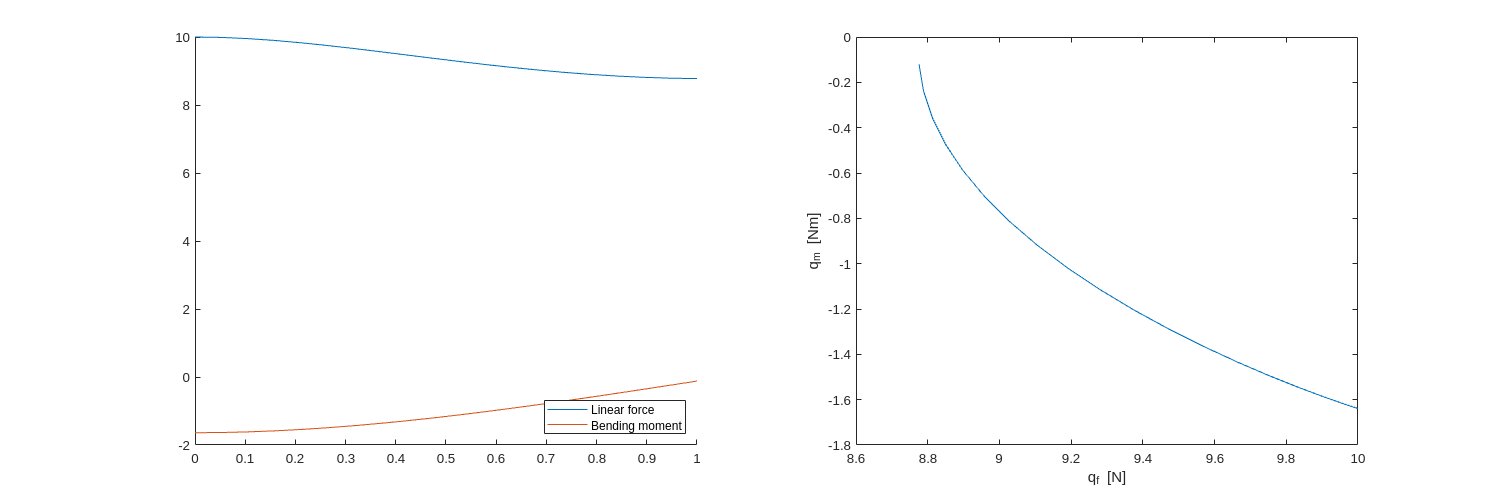

Q_tip = [0; -10; 0];
g_tip = poses(:, :, end);

% TODO: Replace this with a call to our function
q = zeros(3, N_poses);
for i = 1 : N_poses
    g_i = poses(:, :, i);
    g_i_tip = inv(g_i) * g_tip;
    g_ucirc_right_tip = Pose2.left_lifted_action(g_tip)' * Q_tip;
    g_ucirc_right_s = inv(Pose2.adjoint(g_i_tip))' * g_ucirc_right_tip;

    q(:, i) = g_ucirc_right_s;
end
figure("position", [0, 0, 1500, 500]);

subplot(1, 2, 1)
hold on
plot(s, q(1, :));
plot(s, q(3, :));
legend("Linear force", "Bending moment", "location", "southeast")

subplot(1, 2, 2)
plot(q(1, :), q(3, :))
xlabel("q_f [N]")
ylabel("q_m [Nm]")

Now given the pressures of each muscle in the arm, compute the internal reaction force supplied along the length of the arm

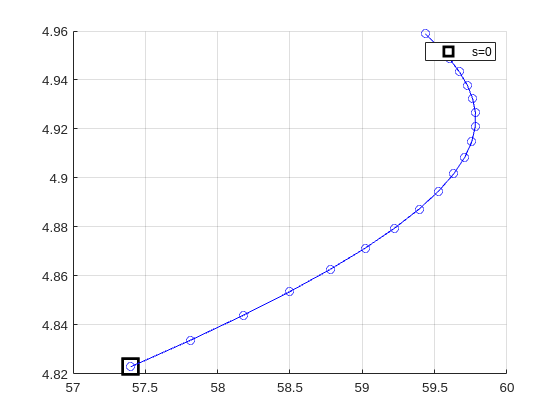

p = [15; 0; 15; 0]; %kPa

% Define actuator forces
f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

rho_outer = 0.08;
rho_inner = 0.015;

rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];

% TODO: Replace this with a call to our function
% Compute the strains of each rods
l_0 = 0.5;
strain_o = (l - l_0) / l_0;

mat_A = [
1, 1, 1, 1;
0, 0, 0, 0;
-rhos;
];

lengths = zeros(4, N_poses);
strains = zeros(4, N_poses);
forces = zeros(4, N_poses);
for i = 1 : length(rhos)
    lengths(i, :) = segment_twists(1, :) - rhos(i) * segment_twists(3, :);
    strains(i, :) = (lengths(i, :) - l_0) / l_0;
    for j = 1 : length(forces)
        forces(i, j) = fs{i}(strains(i, j), p(i));
    end
end

reaction_forces = mat_A * forces;
figure()
hold on
plot(reaction_forces(1, 1), reaction_forces(3, 1), "ksquare", "markersize", 15, "linewidth", 3)
plot(reaction_forces(1, :), reaction_forces(3, :), "b-o")
legend("s=0")
grid on

struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = g_0;
struct_design.rhos = rhos;

f_residual = @(mat_segment_twists) check_equilibrium(mat_segment_twists, Q_tip, p, struct_design);

tic
default_segment_twists = zeros(size(segment_twists));
default_segment_twists(1, :) = l_0;

opts = optimoptions("fsolve", MaxFunctionEvaluations=4e5, MaxIterations=5e3, StepTolerance=1e-8, FunctionTolerance=1e-8, Algorithm="levenberg-marquardt");
[soln, res, ~, output] = fsolve(f_residual, default_segment_twists, opts);


No solution found.

fsolve stopped because the last step was ineffective. However, the vector of function
values is not near zero, as measured by the value of the function tolerance. 

<stopping criteria details>


disp(res)

   -0.0021   -0.0023   -0.0029   -0.0039   -0.0052   -0.0069   -0.0089   -0.0113   -0.0141   -0.0170   -0.0203   -0.0237   -0.0273   -0.0311   -0.0350   -0.0390   -0.0431   -0.0473   -0.0534   -0.0577
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1505    0.1653    0.2063    0.2733    0.3663    0.4848    0.6280    0.7961    0.9847    1.1927    1.4174    1.6569    1.9054    2.1616    2.4211    2.6948    2.9494    3.1996    3.4464    3.7080



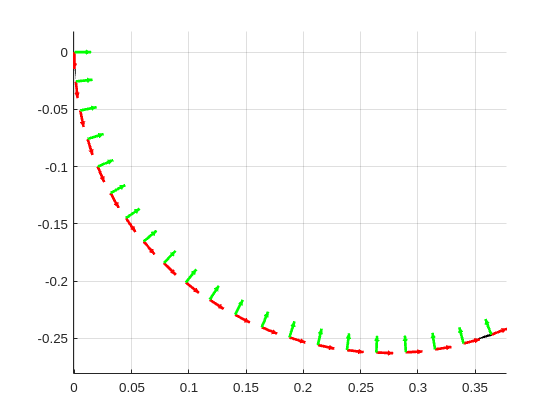


poses = calc_poses(g_0, soln);
ax = axes(figure());
plot_poses(poses, ax);
grid on

toc

Elapsed time is 2.652764 seconds.


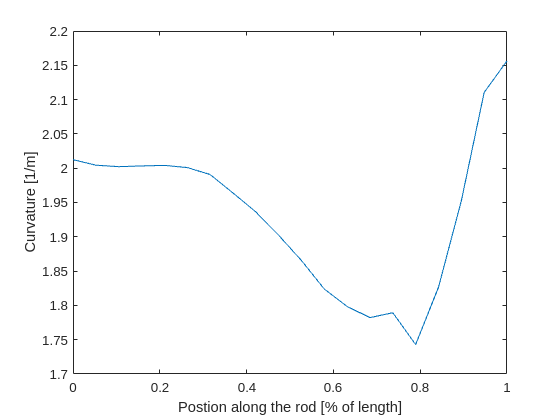

figure()
plot(s, soln(3, :))
xlabel("Postion along the rod [% of length]")
ylabel("Curvature [1/m]")

% Construct a similar arm but using the previous library to check for
% equivalence
tic
arm = ArmSeriesFactory.constant_2d_antagonist_arm(N_poses, rho_inner, rho_outer, l_0);
arm.set_mechanics(JacobBellowMechanics(l_0), [1, 4]);
arm.solve_equilibrium_gina(p, Q_tip, print=true);


No solution found.

fsolve stopped because the last step was ineffective. However, the vector of function
values is not near zero, as measured by the value of the function tolerance. 

<stopping criteria details>
fzero residual is nonzero (> 0.01). Printing: 
  -0.001807637519356  -0.002662525963920  -0.005039164184167  -0.008905598382331  -0.014095236958340  -0.020378832302015  -0.027462072800679  -0.035137816396005  -0.043294170094716  -0.054196501837198
   0.000012744904149   0.000030130515360   0.000058515528808   0.000098282754980   0.000141350952807   0.0001718839839

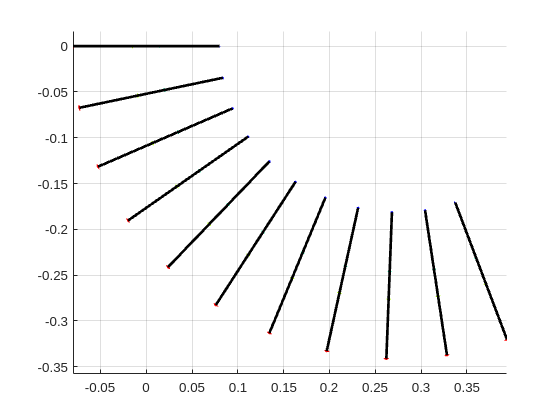

Plotter2D.plot_arm_series(arm, axes(figure()))

toc

Elapsed time is 28.723102 seconds.


function poses = f_calc_poses(g_0, f_segment_twists, N_poses)
    s = linspace(0, 1, N_poses);
    mat_segment_twists = f_segment_twists(s);
    poses = calc_poses(g_0, mat_segment_twists);
end

function plot_poses(poses, ax, linestyle)

    arguments
        poses
        ax
        linestyle="k-";
    end

    axis_length = 0.15;

    % Extract position components
    p_x = squeeze(poses(1, 3, :));
    p_y = squeeze(poses(2, 3, :));

    % Extract x unit vector components
    x_u = squeeze(poses(1, 1, :));
    x_v = squeeze(poses(2, 1, :));

    y_u = squeeze(poses(1, 2, :));
    y_v = squeeze(poses(2, 2, :));

    % Plot
    hold(ax, "on")
    plot(ax, p_x, p_y, linestyle, "linewidth", 2);
    quiver(ax, p_x, p_y, x_u, x_v, axis_length, "red", "linewidth", 2);
    quiver(ax, p_x, p_y, y_u, y_v, axis_length, "green", "linewidth", 2);
    axis(ax, "equal")
end